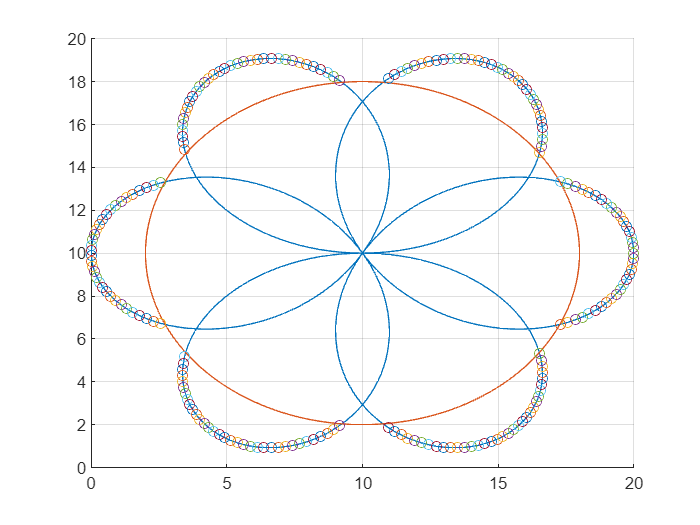

n = 3; % numerador del factor k
d = 2; % denominador del factor k
k = n/d; % Factor que determina la forma de la rosa (Ver Wikipedia)
r = 8; % Radio del círculo que "suaviza"
centro = 10; % Desplazamiento de toda la figura del punto 0,0
a = 10; % Amplitud de la figura

res = 500; % Resolución: Cantidad de puntos de la trayectoria

theta = linspace(0, 4*pi,res);
recta = linspace(10, 20, 2);
x = a.*cos(k*theta).*cos(theta)+centro;
y = a.*cos(k*theta).*sin(theta)+centro;

% Función que haga un vector desde 10,10 hasta todos los puntos de la flor.
% Si la norma de este vector es mayor que el radio del círculo, se
% toma para los puntos finales.

d = 0; % Inicializar la distancia.
trayectoriaX = [0 0]; % Inicializar vectores de la trayectoria 
trayectoriaY = [0 0]; % TO DO: Encontrar una manera más elegante  
for i = 1:length(theta) % Hasta el tamaño de theta porque "x" y "y" toman su tamaño de theta.
    % Calcula la distancia entre el centro y cada punto de la flor (pitágoras)
    d = sqrt((x(i)-centro)^2+(y(i)-centro)^2);
    if d > r % Si la distancia calculada es mayor que el radio del círculo entonces...
        trayectoriaX(i) = x(i); % ...conserva la dupla
        trayectoriaY(i) = y(i);
    end
end

trayectoriaX = trayectoriaX(trayectoriaX>0); % Limpia todos los ceros que quedaron...
trayectoriaY = trayectoriaY(trayectoriaY>0); % ...en ambos vectores

hold on
plot(x, y)
plot(r*cos(theta)+centro,r*sin(theta)+centro)

% TO DO: ORGANIZAR LOS PUNTOS PARA QUE LA TRAYECTORIA SEA CONTINUA!
% Hay 3 pétalos a cada lado de x = 10. Y horizontalmente se separan en 6 y
% en 14 xDDD.
for i = 1:length(trayectoriaY)
    scatter(trayectoriaX(i), trayectoriaY(i))
    pause(0.001)
end
xlim ([0 2*centro])
ylim ([0 2*centro])
grid on